clc; clear; close all;

datasetPath = "C:\Users\shahj\Downloads\archive\Fruits and Vegetables Freshness Detection Dataset";

imds = imageDatastore(datasetPath, ...
    "IncludeSubfolders", true, ...
    "LabelSource", "foldernames");

disp("Total images (original): " + numel(imds.Files));

Total images (original): 70576


badFiles = strings(0);
reset(imds);

for i = 1:numel(imds.Files)
    try
        readimage(imds, i);
    catch 
        badFiles(end+1) = string(imds.Files{i}); %#ok<SAGROW>
    end
end

disp("Unreadable files found: " + numel(badFiles));

Unreadable files found: 4



allFiles = string(imds.Files(:));
goodFiles = setdiff(allFiles, badFiles, "stable");

imds = imageDatastore(cellstr(goodFiles), "LabelSource","foldernames");
disp("Total images (after cleaning): " + numel(imds.Files));

Total images (after cleaning): 70572


maxPerClass = 400;

tbl = countEachLabel(imds);
labels = tbl.Label;

files = {};
labs  = [];

for i = 1:numel(labels)

    % Get datastore of one class
    imdsClass = subset(imds, imds.Labels == labels(i));
    
    numImages = numel(imdsClass.Files);
    
    % Choose number of images
    n = min(maxPerClass, numImages);
    
    % Random selection
    idx = randperm(numImages, n);
    
    files = [files; imdsClass.Files(idx)];
    labs  = [labs; imdsClass.Labels(idx)];
end

% Create new datastore
imdsSmall = imageDatastore(files, "Labels", labs);

disp("Total images (subset): " + numel(imdsSmall.Files))

Total images (subset): 10222



tblSmall = countEachLabel(imdsSmall);
disp(tblSmall)

          Label          Count
    _________________    _____

    FreshApple            400 
    FreshBanana           400 
    FreshBellpepper       400 
    FreshBittergroud      327 
    FreshCapciscum        400 
    FreshCarrot           400 
    FreshCucumber         400 
    FreshMango            400 
    FreshOkara            400 
    FreshOrange           400 
    FreshPotato           400 
    FreshStrawberry       400 
    FreshTomato           400 
    RottenApple           400 
    RottenBanana          400 
    RottenBellpepper      400 
    RottenBittergroud     357 
    RottenCapsicum        400 
    RottenCarrot          400 
    RottenCucumber        400 
    RottenMango           400 
    RottenOkra            338 
    RottenOrange          400 
    RottenPotato          400 
    RottenStrawberry      400 
    RottenTomato          400 



[imdsTrain, imdsTemp] = splitEachLabel(imdsSmall, 0.7, "randomized");
[imdsVal, imdsTest]   = splitEachLabel(imdsTemp, 0.5, "randomized");

disp("Train: " + numel(imdsTrain.Files));

Train: 7156


disp("Val:   " + numel(imdsVal.Files));

Val:   1534


disp("Test:  " + numel(imdsTest.Files));

Test:  1532


inputSize = [224 224 3];

augmenter = imageDataAugmenter( ...
    "RandRotation",[-10 10], ...
    "RandXReflection",true);

augTrain = augmentedImageDatastore(inputSize, imdsTrain, ...
    "DataAugmentation", augmenter, ...
    "ColorPreprocessing","gray2rgb");

augVal = augmentedImageDatastore(inputSize, imdsVal, ...
    "ColorPreprocessing","gray2rgb");

augTest = augmentedImageDatastore(inputSize, imdsTest, ...
    "ColorPreprocessing","gray2rgb");

disp("Augmented datastores ready.");

Augmented datastores ready.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:17 |        0.00% |        3.52% |       4.4790 |       3.7194 |      1.0000e-04 |
|       1 |          30 |       00:01:03 |        9.38% |       21.38% |       3.6860 |       2.7272 |      1.0000e-04 |
|       1 |          50 |       00:01:23 |       21.88% |              |       2.7511 |              |      1.0000e-04 |
|       1 |          60 |       00:01:46 |       28.12% |       23.92% |       2.6289 |   

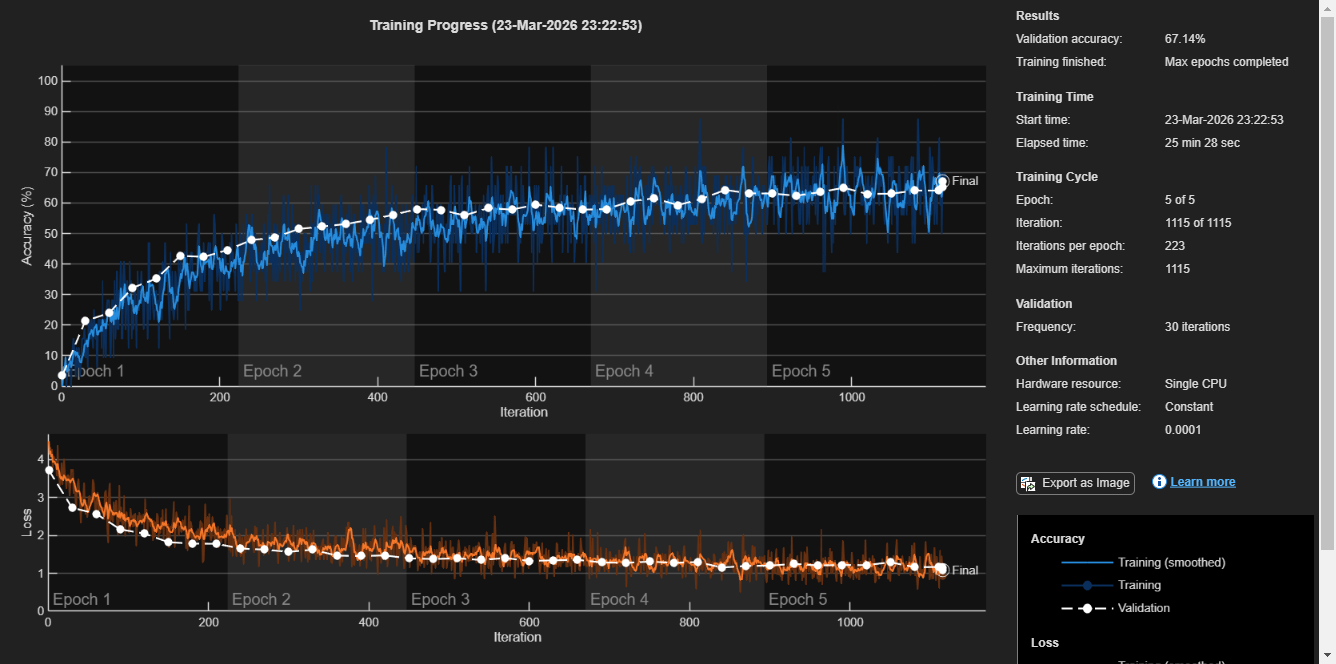

%% BASE CNN MODEL

numClasses = numel(categories(imdsTrain.Labels));

layersBase = [
    imageInputLayer([224 224 3])

    convolution2dLayer(3,8,"Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,16,"Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,32,"Padding","same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(0.5)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
];

optionsBase = trainingOptions("sgdm", ...
    "InitialLearnRate",0.0001, ...
    "MiniBatchSize",32, ...
    "MaxEpochs",5, ...
    "ValidationData",augVal, ...
    "ValidationFrequency",30, ...
    "Shuffle","every-epoch", ...
    "Plots","training-progress", ...
    "Verbose",true);

baseNet = trainNetwork(augTrain, layersBase, optionsBase);

%% EVALUATE BASE CNN

YPred_base = classify(baseNet, augTest);
YTest = imdsTest.Labels;

baseAcc = mean(YPred_base == YTest) * 100;
disp("Base CNN Test Accuracy (%): " + baseAcc);

Base CNN Test Accuracy (%): 65.8616


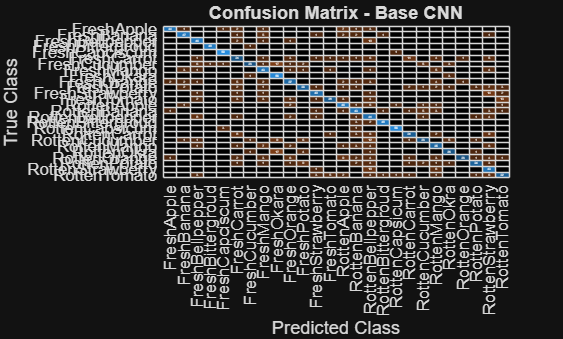


figure;
confusionchart(YTest, YPred_base);
title("Confusion Matrix - Base CNN");

exportgraphics(gcf, "confusion_matrix_basecnn.png", "Resolution",300);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:50 |        6.25% |        6.45% |       4.4372 |       4.0972 |      1.0000e-04 |
|       1 |          30 |       00:05:34 |       65.62% |       74.19% |       1.0132 |       0.8598 |      1.0000e-04 |
|       1 |          50 |       00:07:16 |       68.75% |              |       0.9055 |              |      1.0000e-04 |
|       1 |          60 |       00:09:18 |       84.38% |       85.01% |       0.3559 |   

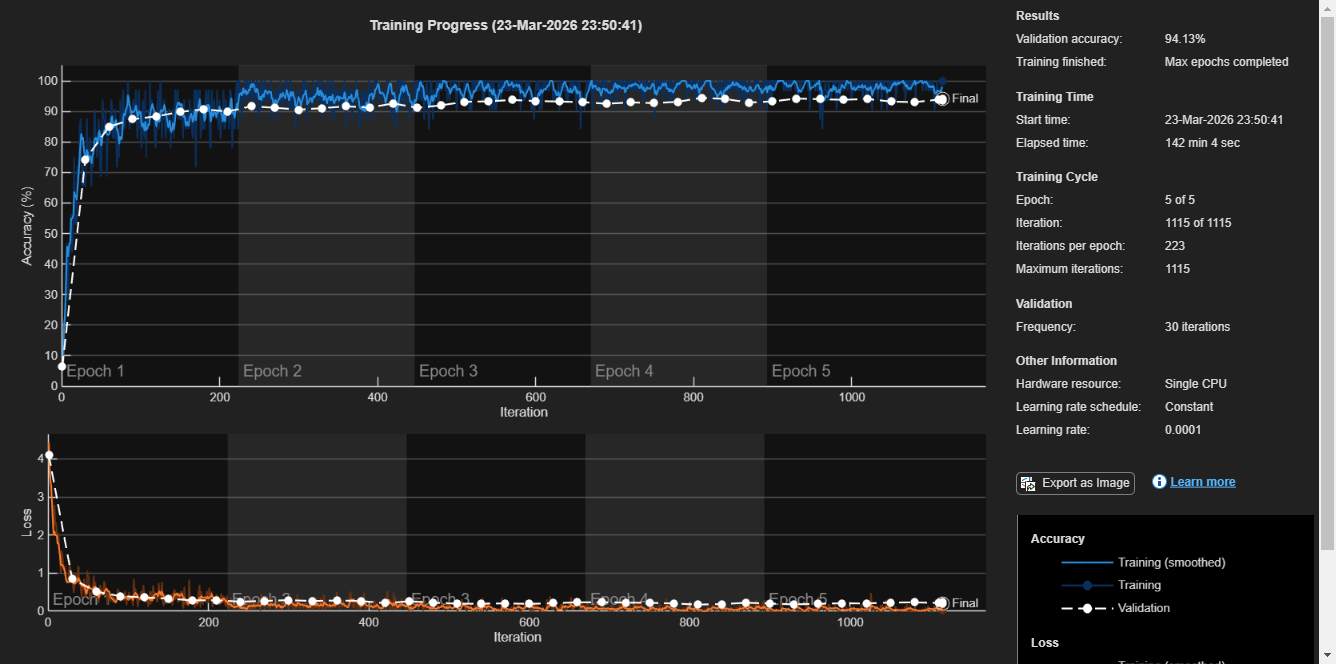

%% RESNET18 MODEL

net = resnet18;
lgraph = layerGraph(net);

numClasses = numel(categories(imdsTrain.Labels));

lgraph = removeLayers(lgraph, {'fc1000','prob','ClassificationLayer_predictions'});

newHead = [
    fullyConnectedLayer(numClasses, "Name","fc_new", ...
        "WeightLearnRateFactor",10, "BiasLearnRateFactor",10)
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classOutput")
];

lgraph = addLayers(lgraph, newHead);
lgraph = connectLayers(lgraph, "pool5", "fc_new");

optionsResNet = trainingOptions("adam", ...
    "MiniBatchSize", 32, ...
    "MaxEpochs", 5, ...
    "InitialLearnRate", 1e-4, ...
    "ValidationData", augVal, ...
    "ValidationFrequency", 30, ...
    "Shuffle","every-epoch", ...
    "Plots","training-progress", ...
    "Verbose", true);

trainedNet = trainNetwork(augTrain, lgraph, optionsResNet);

%% EVALUATE RESNET18

YPred_resnet = classify(trainedNet, augTest);
YTest = imdsTest.Labels;

resnetAcc = mean(YPred_resnet == YTest) * 100;
disp("ResNet18 Test Accuracy (%): " + resnetAcc);

ResNet18 Test Accuracy (%): 94.1253


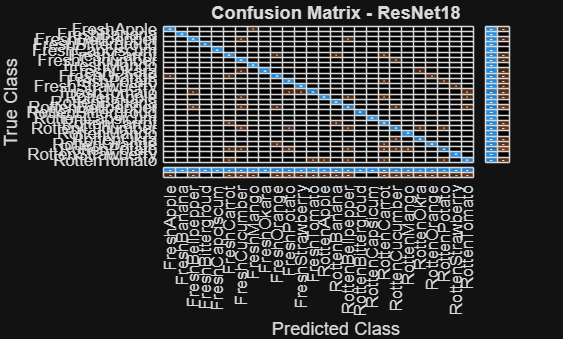


figure;
confChart = confusionchart(YTest, YPred_resnet);
confChart.Title = 'Confusion Matrix - ResNet18';
confChart.RowSummary = 'row-normalized';
confChart.ColumnSummary = 'column-normalized';

exportgraphics(gcf, "confusion_matrix_resnet18.png", "Resolution",300);

%% COMPARE BOTH MODELS

disp(" ");

disp("===== MODEL COMPARISON =====");

===== MODEL COMPARISON =====


disp("Base CNN Accuracy (%): " + baseAcc);

Base CNN Accuracy (%): 65.8616


disp("ResNet18 Accuracy (%): " + resnetAcc);

ResNet18 Accuracy (%): 94.1253



if resnetAcc > baseAcc
    disp("ResNet18 performed better than Base CNN.");
elseif baseAcc > resnetAcc
    disp("Base CNN performed better than ResNet18.");
else
    disp("Both models achieved the same accuracy.");
end

ResNet18 performed better than Base CNN.


%% SAVE MODELS

save("fruitFreshness_comparison_models.mat", ...
    "baseNet", "trainedNet", "baseAcc", "resnetAcc");

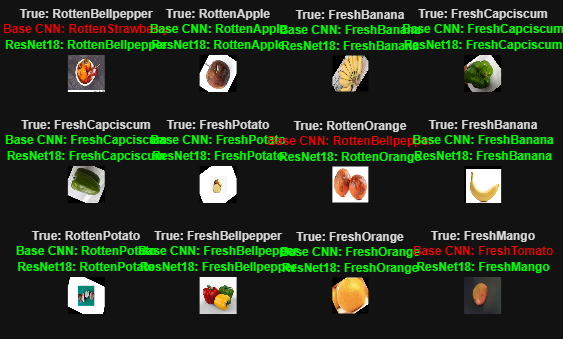

figure;
idx = randperm(numel(imdsTest.Files), 12);
tiledlayout(3,4,"Padding","compact","TileSpacing","compact");

for i = 1:12
    nexttile
    I = readimage(imdsTest, idx(i));
    imshow(imresize(I,[224 224]))
    
    trueLabel = string(YTest(idx(i)));
    predBase = string(YPred_base(idx(i)));
    predRes = string(YPred_resnet(idx(i)));
    
    % color for Base CNN
    if trueLabel == predBase
        baseColor = '\color{green}';
    else
        baseColor = '\color{red}';
    end
    
    % color for ResNet
    if trueLabel == predRes
        resColor = '\color{green}';
    else
        resColor = '\color{red}';
    end
    
    title({
        "True: " + trueLabel
        baseColor + "Base CNN: " + predBase
        resColor + "ResNet18: " + predRes
        }, "FontSize",7, "Interpreter","tex");
end

exportgraphics(gcf,"sample_predictions.png","Resolution",300);